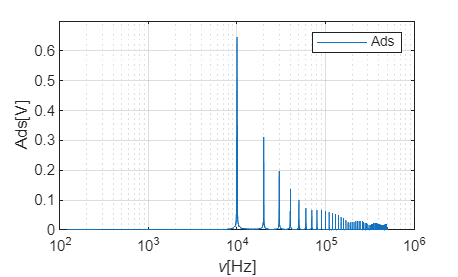

clear all
cd(fileparts(matlab.desktop.editor.getActiveFilename))


tbl1 = readtable("SL01.txt", NumHeaderLines=3);
tbl1.Properties.VariableNames = ["t", "Ch1"];
N = length(tbl1.t);
fs = 1 / min(diff(tbl1.t));
XTv = fft(tbl1.Ch1);
fv = (0:(N/2))*fs/N;
Av = abs(XTv(1:N/2+1))/N;
Av(2:end-1) = 2*Av(2:end-1);
semilogx(fv, Av)
legend("Ads")
xlabel("\nu[Hz]")
ylabel("Ads[V]")
grid on

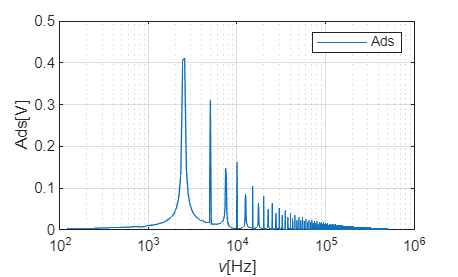



tbl2 = readtable("SL02.txt", NumHeaderLines=3);
tbl2.Properties.VariableNames = ["t", "Ch1"];
N = length(tbl2.t);
fs = 1 / min(diff(tbl2.t));
XTv = fft(tbl2.Ch1);
fv = (0:(N/2))*fs/N;
Av = abs(XTv(1:N/2+1))/N;
Av(2:end-1) = 2*Av(2:end-1);
semilogx(fv, Av)
legend("Ads")
xlabel("\nu[Hz]")
ylabel("Ads[V]")
grid on

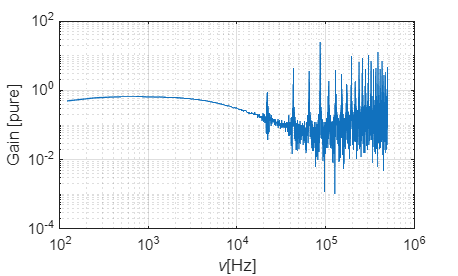

tbl3 = readtable("FFT01.txt", NumHeaderLines=3);
tbl3.Properties.VariableNames = ["t", "Vin", "Vout"];
Hv = fft(tbl3.Vout)./fft(tbl3.Vin);
Hv = Hv(1:N/2+1);
fv = (0:N/2)*fs/N;
loglog(fv, abs(Hv))
xlabel("\nu[Hz]")
ylabel("Gain [pure]")
grid on

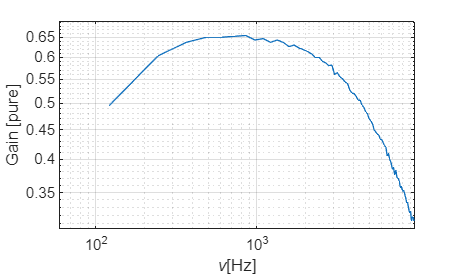

mask = fv < 10^4;
fv = fv(mask);
Hv = Hv(mask);
loglog(fv, abs(Hv))
xlabel("\nu[Hz]")
ylabel("Gain [pure]")
grid on